MultiObjectiveOptimTest2

GA Multi Objective

Optimization terminated: average change in the spread of Pareto solutions less than options.FunctionTolerance.


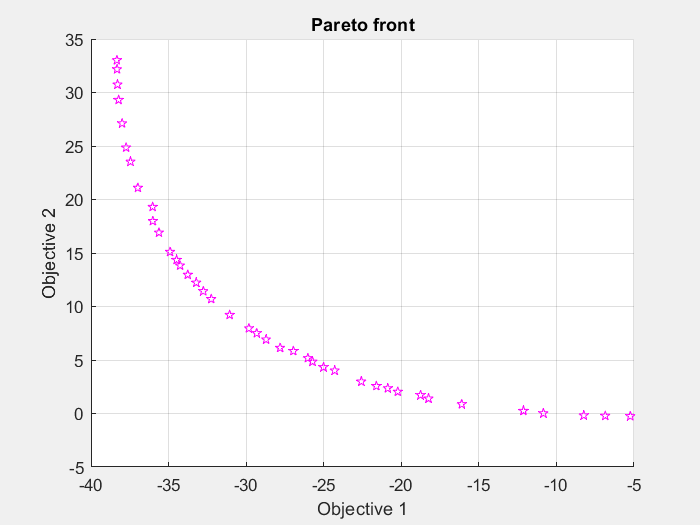

Solution =     2.6711   -1.9737
    0.7063   -0.7062
    2.4098   -1.7570
    1.1121   -1.0763
    1.4013   -1.1491
    2.5018   -1.8311
    2.6274   -1.9426
    0.7063   -0.7062
    2.2099   -1.7188
    2.4696   -1.7702


ObjectiveValue =   -38.3333   33.0159
   -5.2382   -0.2500
  -36.9793   21.0909
  -12.1258    0.2419
  -18.2412    1.3966
  -37.7400   24.8514
  -38.2916   30.7407
   -5.2382   -0.2500
  -34.4854   14.3531
  -37.4560   23.5310


options = optimoptions ('gamultiobj', 'PopulationSize', 60, ...
    'ParetoFraction', 0.7, 'PlotFcn', 'gaplotpareto') ;
lb = [0 -5] ;
ub = [5 0] ;
nvars = 2 ;
[Solution, ObjectiveValue] = gamultiobj (@multiObjFcn1, nvars, [], [], [], [], lb, ub, [], options )

ParetoSearch


Pareto set found that satisfies the constraints. 

Optimization completed because the relative change in the volume of the Pareto set 
is less than 'options.ParetoSetChangeTolerance' and constraints are satisfied to within 
'options.ConstraintTolerance'.



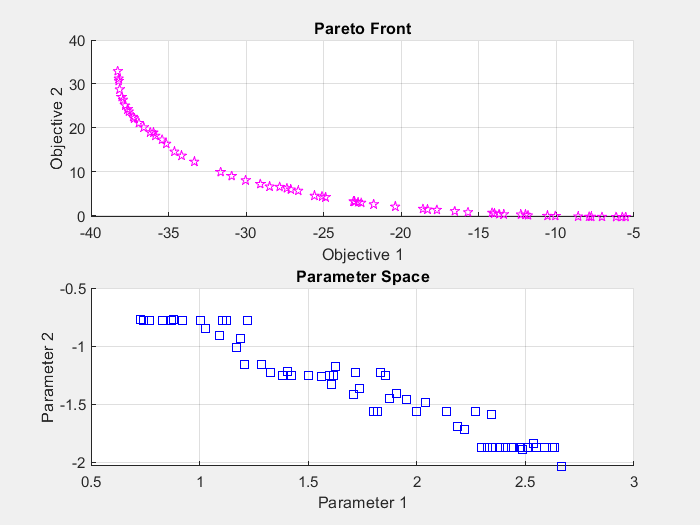

xp =     1.3813   -1.2500
    1.7373   -1.3687
    2.4452   -1.8750
    1.6187   -1.2500
    1.8560   -1.2500
    1.7989   -1.5625
    1.8198   -1.5625
    2.3818   -1.8750
    1.2858   -1.1620
    2.5508   -1.8750


fvalp =   -17.7070    1.3742
  -25.5952    4.5871
  -37.2864   22.5024
  -23.0115    3.1889
  -27.8413    6.6044
  -26.6392    5.7211
  -27.1166    5.9985
  -36.5977   20.1331
  -15.7031    0.8302
  -38.0279   27.0360


psouput = struct with fields:
         iterations: 19
          funccount: 4560
             volume: 955.3807
    averagedistance: 0.0320
             spread: 0.2622
      maxconstraint: 0
            message: 'Pareto set found that satisfies the constraints. ↵↵Optimization completed because the relative change in the volume of the Pareto set ↵is less than 'options.ParetoSetChangeTolerance' and constraints are satisfied to within ↵'options.ConstraintTolerance'.'
           rngstate: [1×1 struct]


rng default 
nvars = 2 ;
options = optimoptions ('paretosearch', ...
    'PlotFcn',{'psplotparetof', 'psplotparetox'}) ;

[xp, fvalp, ~, psouput] = paretosearch (@multiObjFcn1, nvars, [], [], [], [], lb, ub, [], options)

writematrix (ObjectiveValue, 'GAMultiObjOptim.xlsx', 'Sheet', 'ObjectiveValue')
writematrix (Solution, 'GAMultiObjOptim.xlsx', 'Sheet', 'Solution')

writematrix (fvalp, 'GAMultiObjOptim.xlsx', 'Sheet', 'ObjectiveValue2')
writematrix (xp, 'GAMultiObjOptim.xlsx', 'Sheet', 'Solution2')

function F = multiObjFcn1 (optimInput)
% Example:
% Minimize F(x,y) where
% F(1) = x^2 + y^2
% F(2) = 2 + 0.5*((x-2)^2 + (y+1)^2)

% Edit the lines below with your calculation
x = optimInput(1);
y = optimInput(2);
F(2) = x^4 + y^4 + x*y -(x*y)^2 ;
F(1) = F(2) - 10*x^2 ;


end
